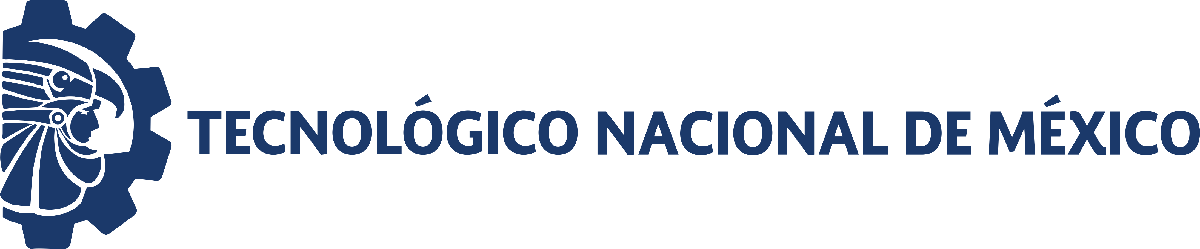                                 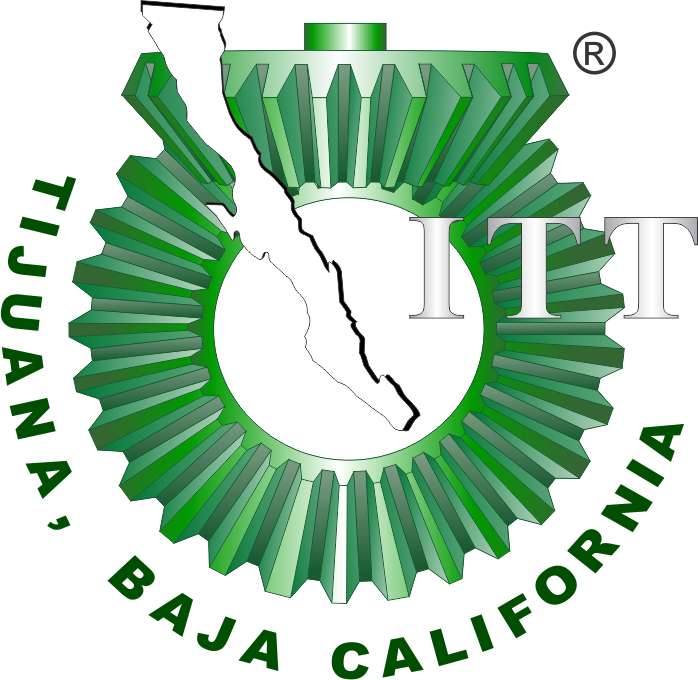

# Práctica 4: Sistema Endocrino

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

                                                                     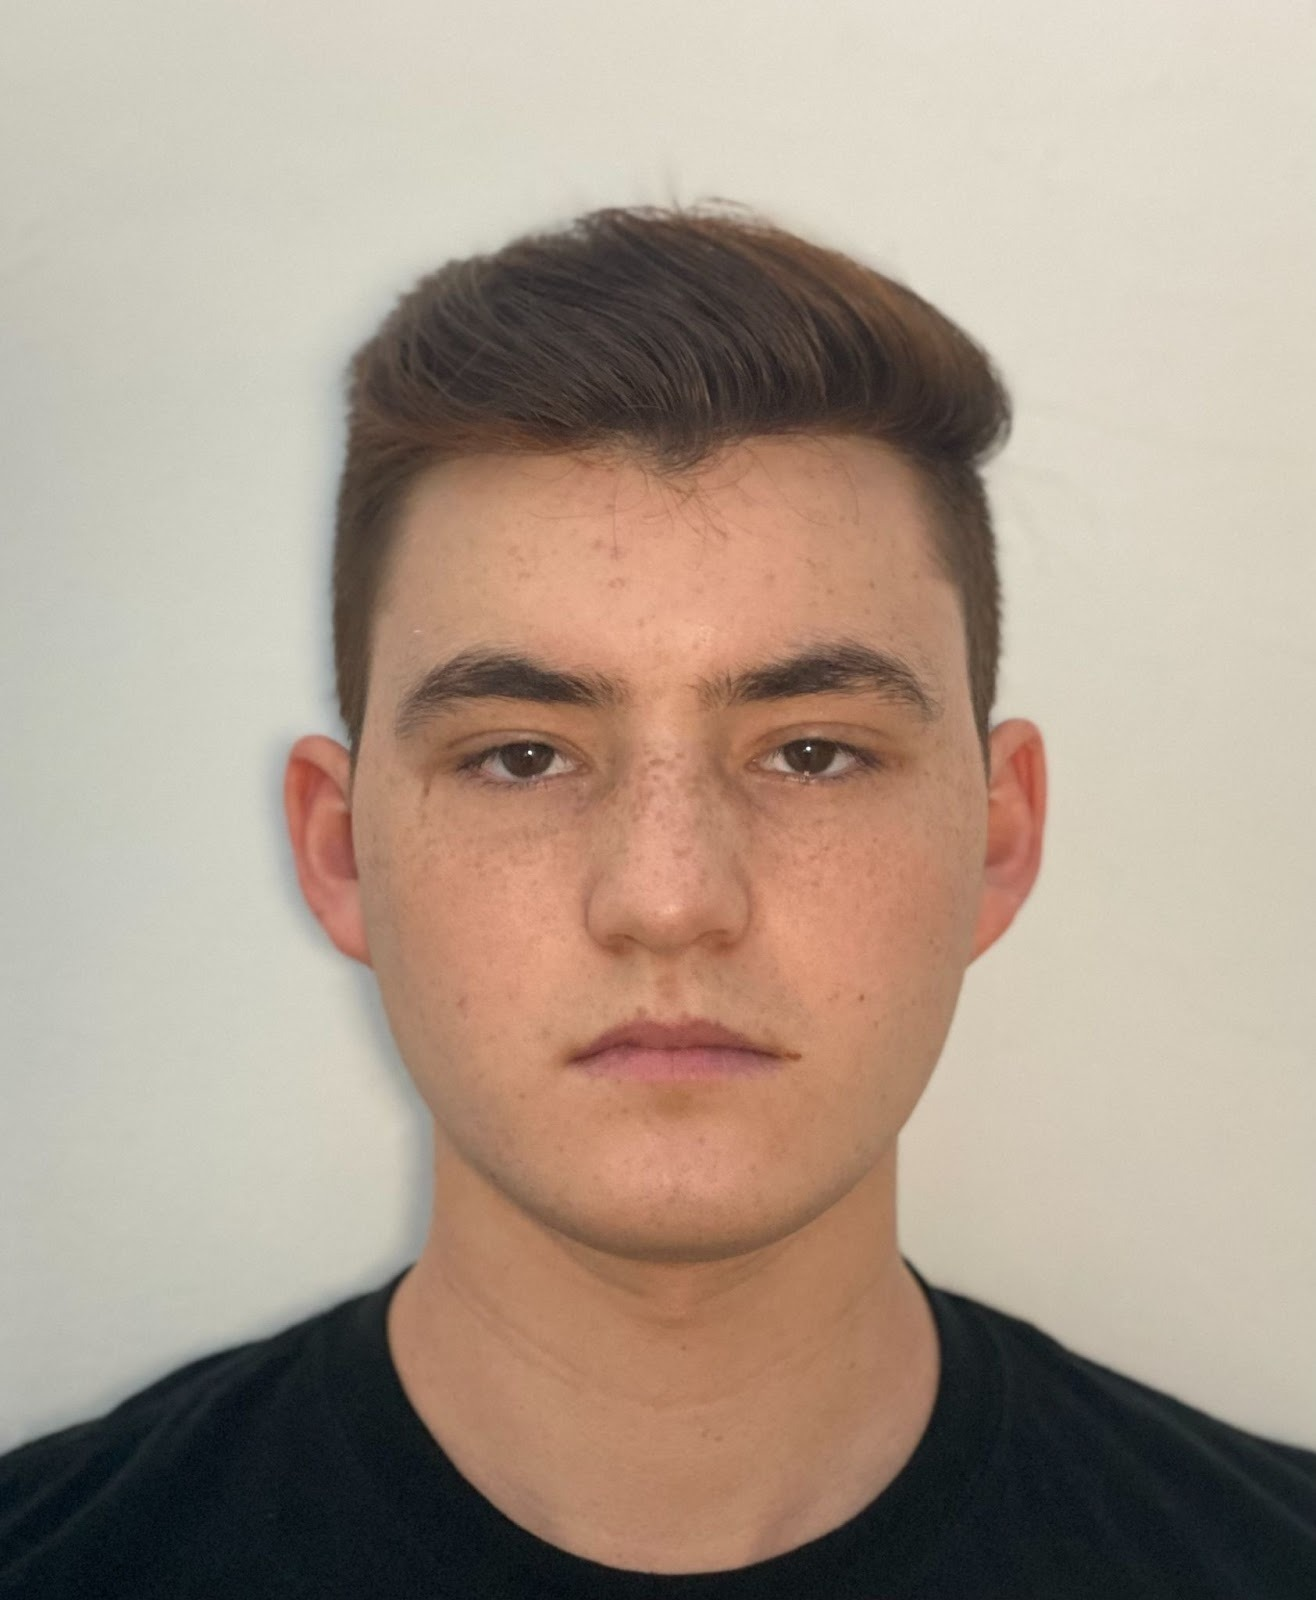

Nombre del alumno: Marco Antonio Campoy Alegria

Número de control: 21212145

Correo institucional: L21212145@tectijuana.edu.mx

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
file = 'Sistema';
open_system(file);
parameter.StopTime = '15';
parameter.Solver = 'ode15s';
parameter.MaxStep = '1E-3';
x = sim(file,parameter);

## Respuesta del sistema

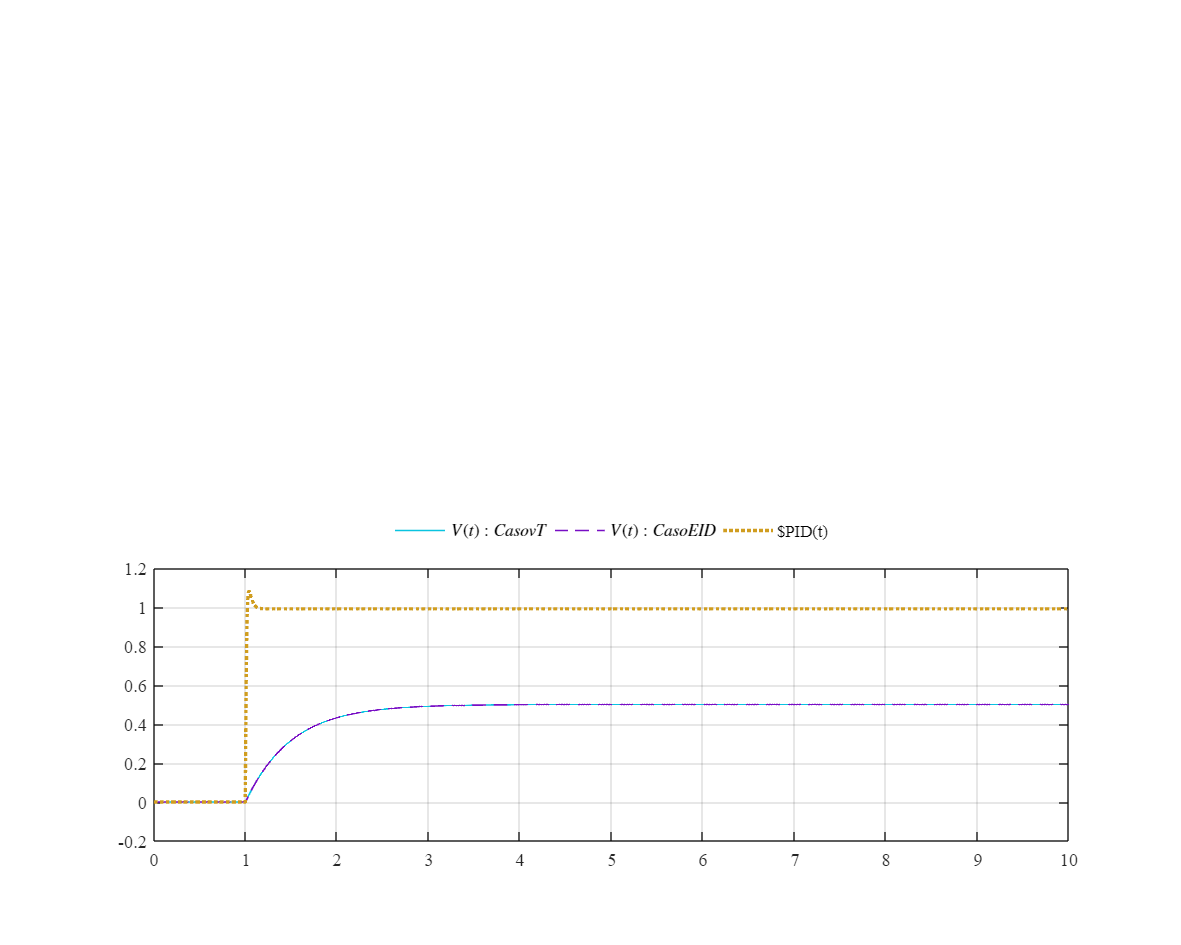

plotsignals(x.t, x.Ve, x.Vs1, x.Vs2, x.Vs3, x.Vs4, x.Vs5, x.PID)

## Funcion de las señales

function plotsignals(t, Ve, Vs1, Vs2, Vs3, Vs4, Vs5, PID)
    set(figure(), 'Color', 'w') 
    set(gcf, 'units', 'centimeters', 'position', [1,1,25,20]) 
    
    % Paleta de colores original [cite: 81-83]
    powerrangers = [10,196,224; 120,14,197; 208,157,31]/255;
    colororder(powerrangers) 
  
    %% Subplot : Respuesta del Caso 
    subplot(2,1,2); box on; hold on; 
    plot(t, Vs4, '-', 'LineWidth', 1);   % Caso FT
    plot(t, Vs5, '--', 'LineWidth', 1);  % Caso EID
    plot(t, PID, ':', 'LineWidth', 2);   % PID Caso
    
    L2 = legend('$V(t): Caso VT$', '$V(t): Caso EID$', '$PID(t)');
    set(L2, 'Interpreter', 'Latex', 'FontSize', 10, 'location', 'NorthOutside', 'Orientation', 'Horizontal', 'box', 'off') 
    
  
    xlim([0, 10]); xticks(0:1:10); grid on;
    ylim([-0.2, 1.2]); yticks(-0.2:0.2:1.2); 
    set(gca, 'FontName', 'Times New Roman', 'FontSize', 11);

    % Exportación opcional
    exportgraphics(gcf, 'Graficas Endocrino.pdf', 'ContentType', 'vector')
end